# Final Project-Main page

 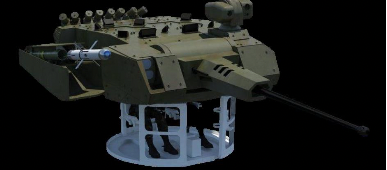

## Simulation Code Map

## Update Workspace for simulations

% load('Workspace_Project22_6.mat')

## Mechanical Parameters and mesurmants

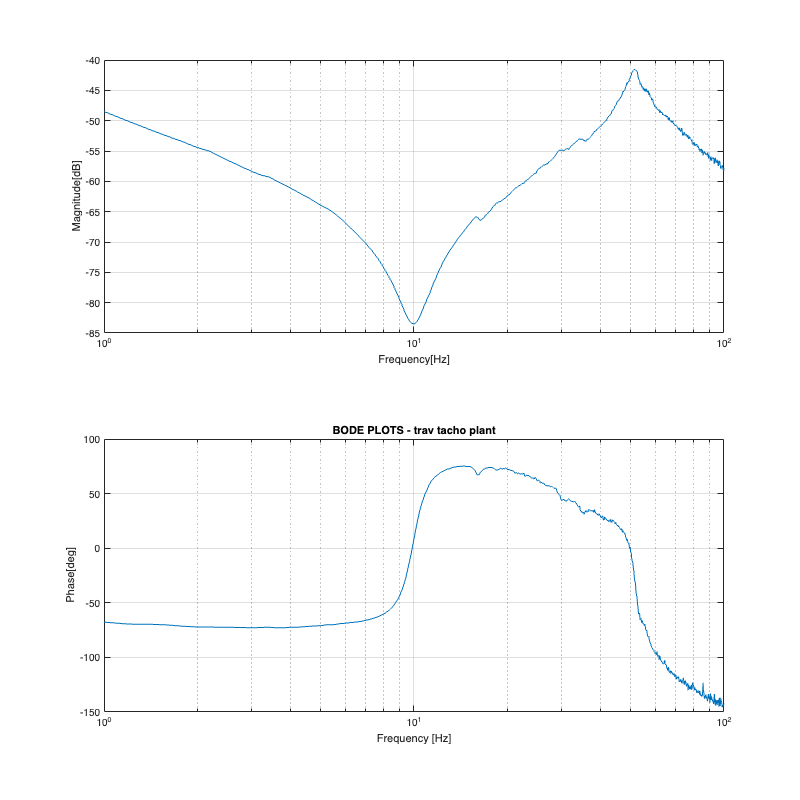

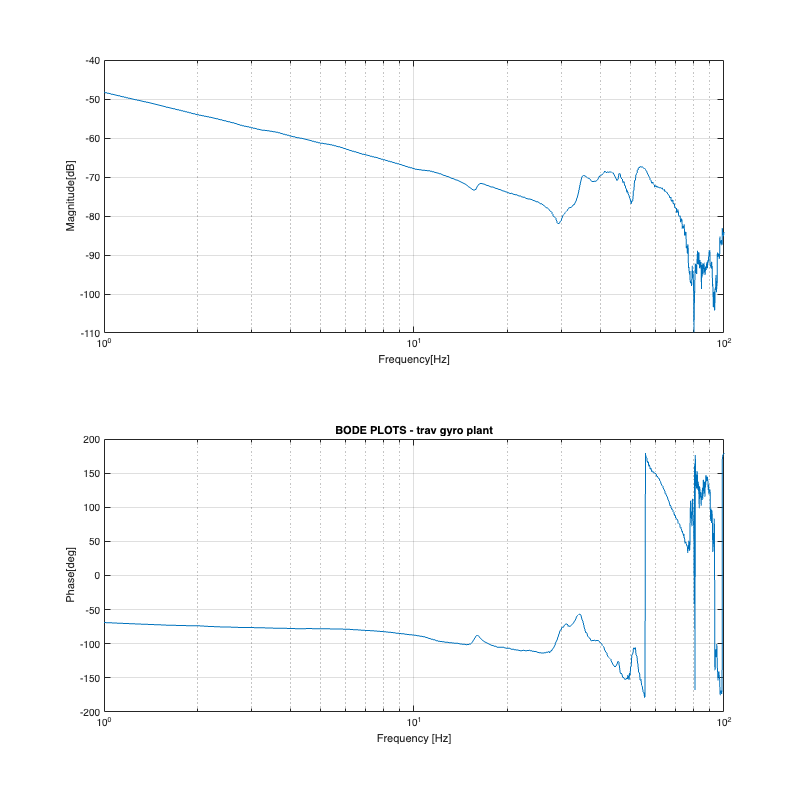

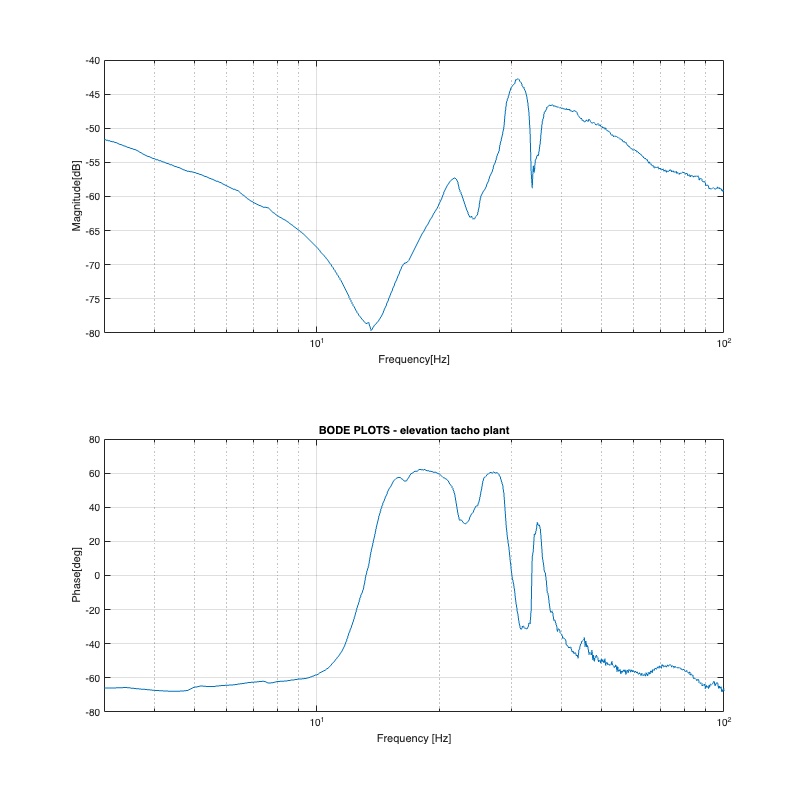

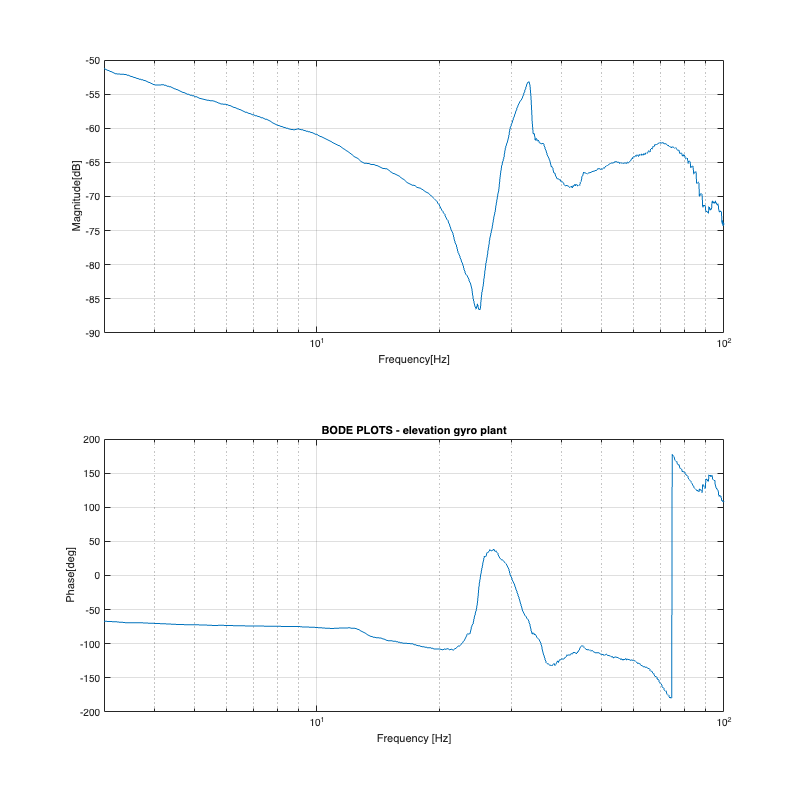

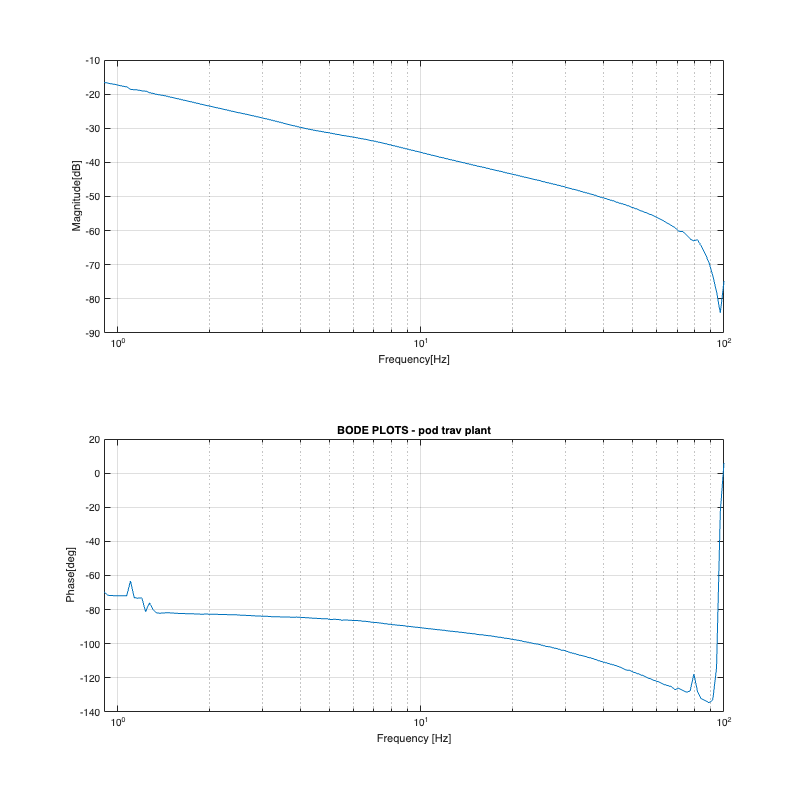

run('Param_catalog.mlx');
run('Raw_Data_Representation.mlx');

## Parametrs estimation , Bode match

run('elevation_gyro_Plant.mlx');
run('elevation_tacho_Plant.mlx');
run('trav_gyro_Plant_2_simple.mlx');
run('Traverse_techo_plant.mlx');

## Get simulation transfer functions

run('open_simulation_ports.mlx');

## Controllerers and plants from simulation and mesurmant

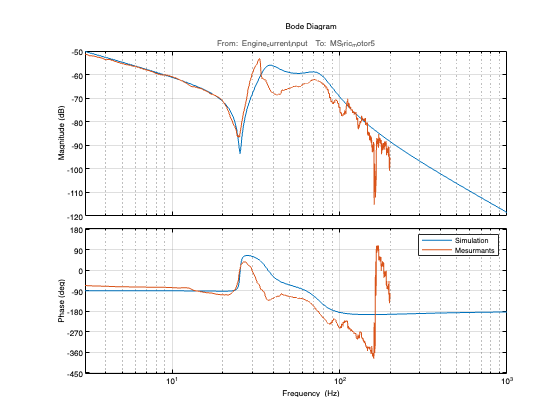

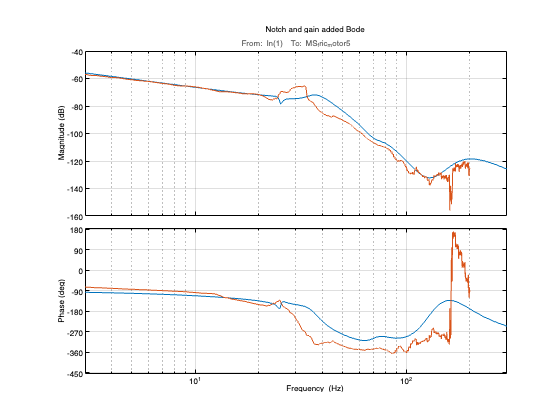

C_pi_elev_gyro =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.83e+03, Ki = 1.76e+03
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 55
           PhaseMargin: 69.6926


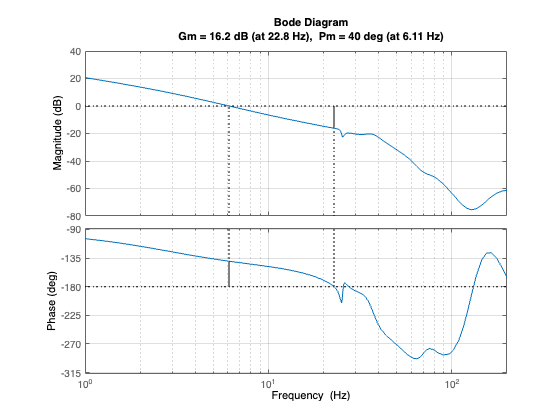

ans = struct with fields:
     GainMargin: [1.7130 1.7235e+03 358.9165]
    GMFrequency: [225.6420 836.7580 1.3107e+03]
    PhaseMargin: 65.5765
    PMFrequency: 70.2122
    DelayMargin: 0.0163
    DMFrequency: 70.2122
         Stable: 1


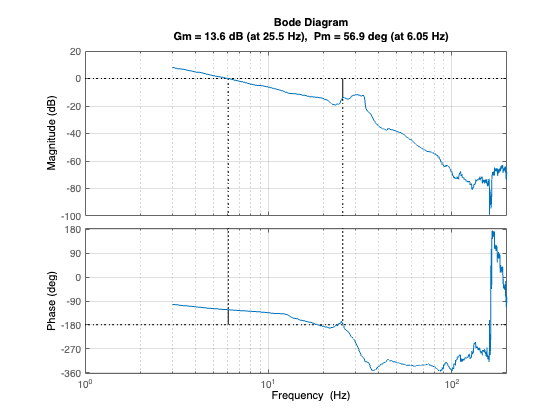

run('elevation_gyro_controller.mlx');

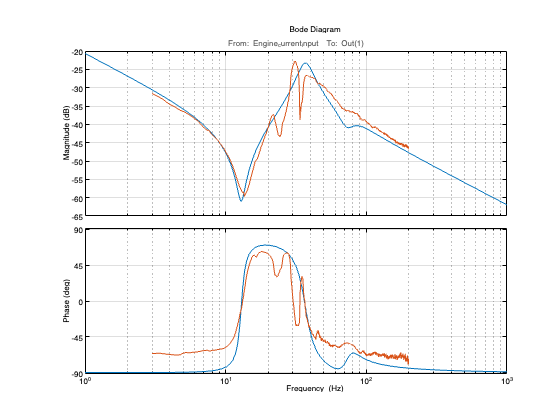

C_pi_elev_techo =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 104, Ki = 2.31e+04
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 280
           PhaseMargin: 53.4216


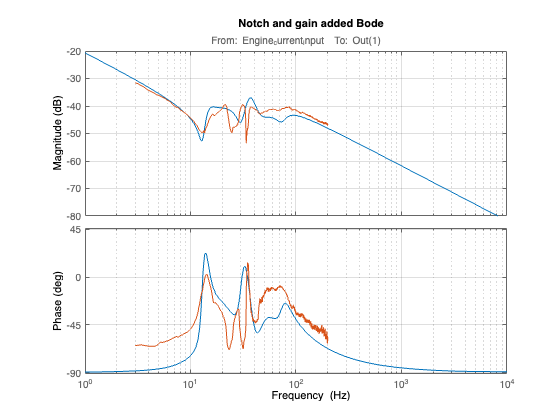

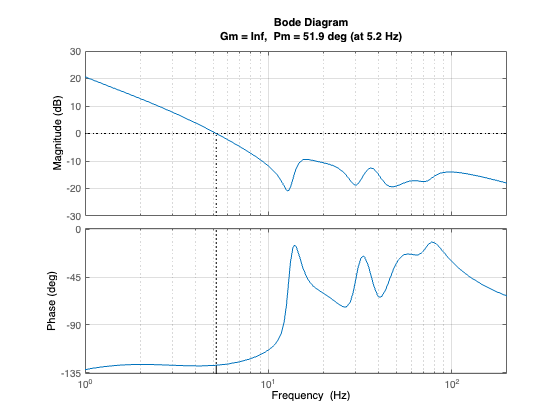

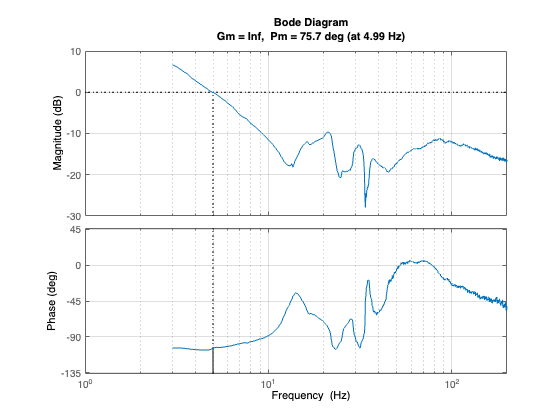

run('elevation_techo_controller.mlx');

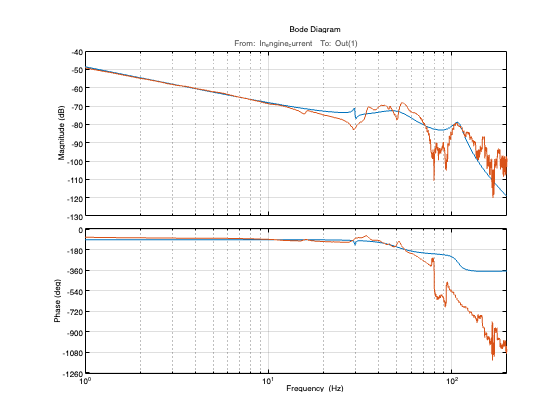

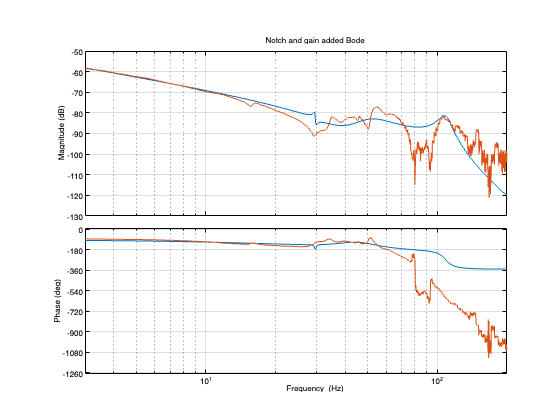

C_pi_trav_gyro_simple =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 690, Ki = 1.37e+04
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 21.7000
           PhaseMargin: 40.0000


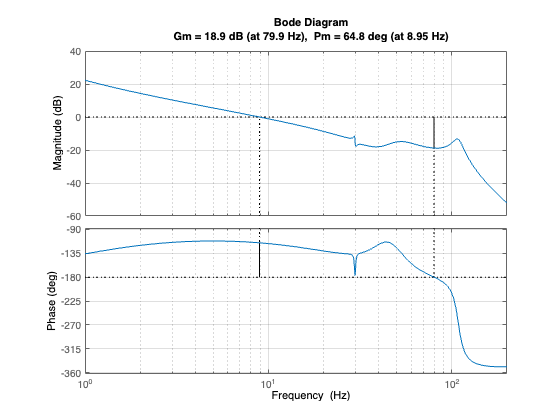

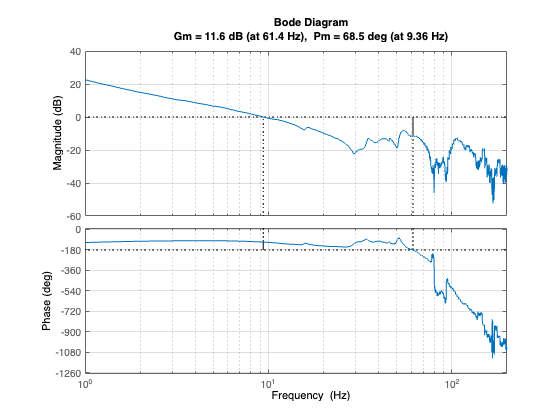

% run('trav_gyro_controller.mlx');
run('trav_gyro_2_simple_controller.mlx');

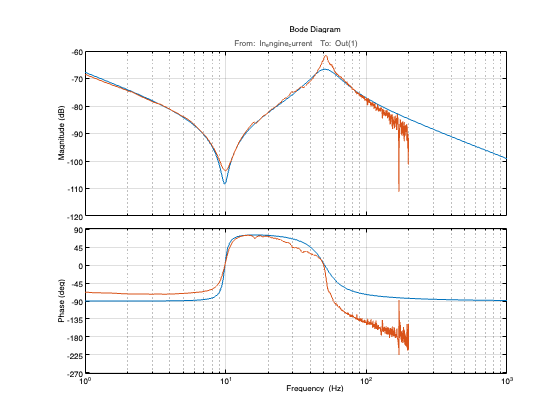

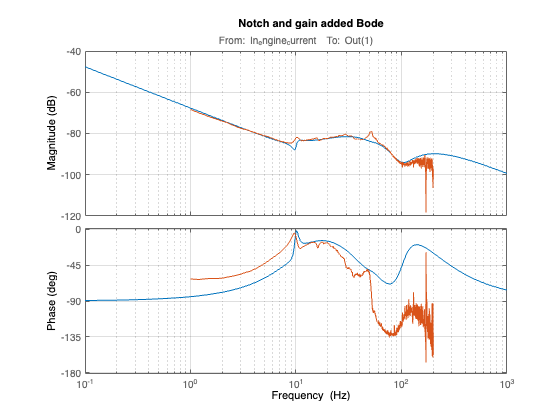

C_pi_trav_techo =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.43e+04, Ki = 3.37e+06
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 360
           PhaseMargin: 90


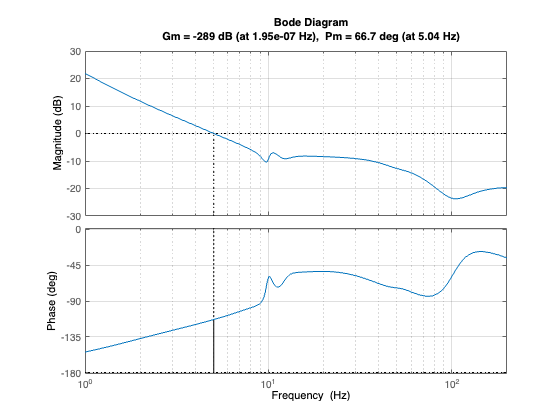

ans = struct with fields:
     GainMargin: 9.1137e-16
    GMFrequency: 6.3137e-07
    PhaseMargin: [112.7325 158.3349 154.6981 158.5457 129.2335]
    PMFrequency: [41.7350 67.6112 70.4821 98.2103 288.3441]
    DelayMargin: [0.0471 0.0409 0.0383 0.0282 0.0078]
    DMFrequency: [41.7350 67.6112 70.4821 98.2103 288.3441]
         Stable: 1


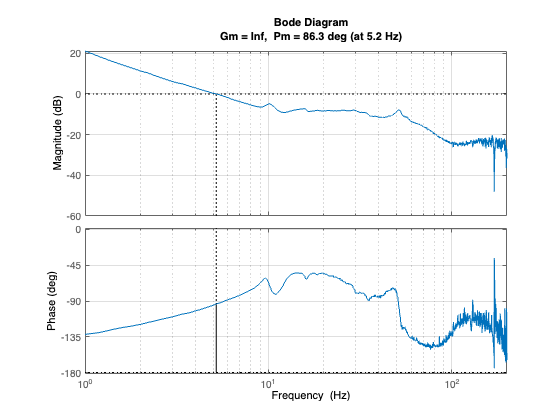

run('trav_techo_controller.mlx');